fc = 77e9;
c = 3e8;
lambda = c/fc;
Nt = 2;
Nr = 4;


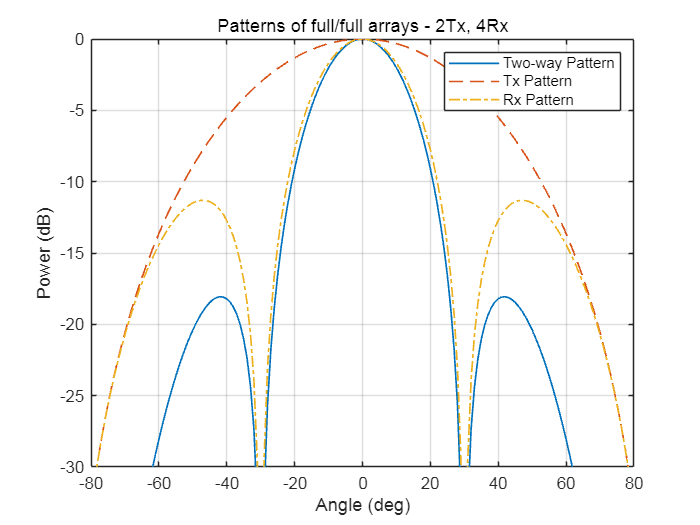

dt = lambda/2;
dr = lambda/2;

txarray = phased.ULA(Nt,dt);
rxarray = phased.ULA(Nr,dr);

ang = -90:90;

pattx = pattern(txarray,fc,ang,0,'Type','powerdb');
patrx = pattern(rxarray,fc,ang,0,'Type','powerdb');
pat2way = pattx+patrx;

helperPlotMultipledBPattern(ang,[pat2way pattx patrx],[-30 0],...
    {'Two-way Pattern','Tx Pattern','Rx Pattern'},...
    'Patterns of full/full arrays - 2Tx, 4Rx',...
    {'-','--','-.'});

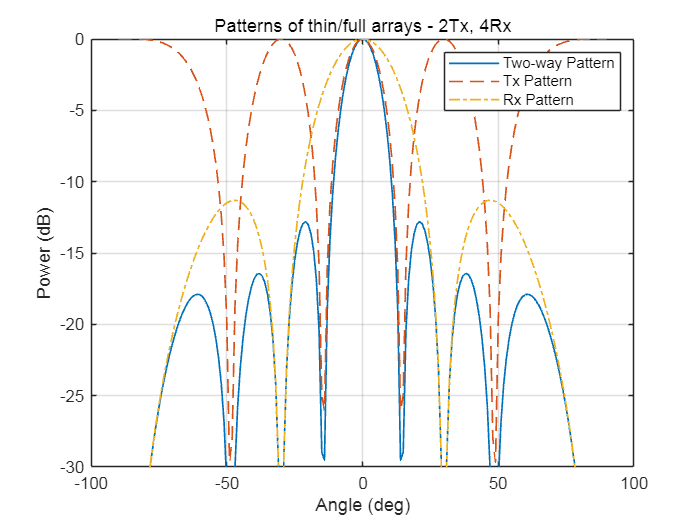

dt = Nr*lambda/2;
txarray = phased.ULA(Nt,dt);
pattx = pattern(txarray,fc,ang,0,'Type','powerdb');
pat2way = pattx+patrx;
helperPlotMultipledBPattern(ang,[pat2way pattx patrx],[-30 0],...
    {'Two-way Pattern','Tx Pattern','Rx Pattern'},...
    'Patterns of thin/full arrays - 2Tx, 4Rx',...
    {'-','--','-.'});

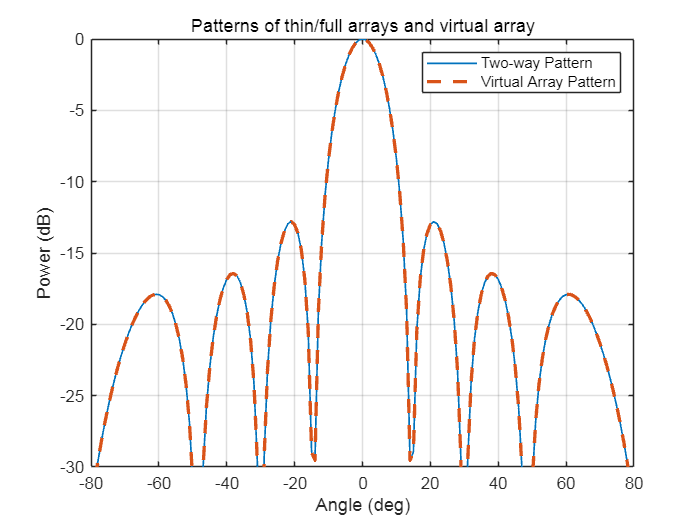

varray = phased.ULA(Nt*Nr,dr);
patv = pattern(varray,fc,ang,0,'Type','powerdb');
helperPlotMultipledBPattern(ang,[pat2way patv],[-30 0],...
    {'Two-way Pattern','Virtual Array Pattern'},...
    'Patterns of thin/full arrays and virtual array',...
    {'-','--'},[1 2]);